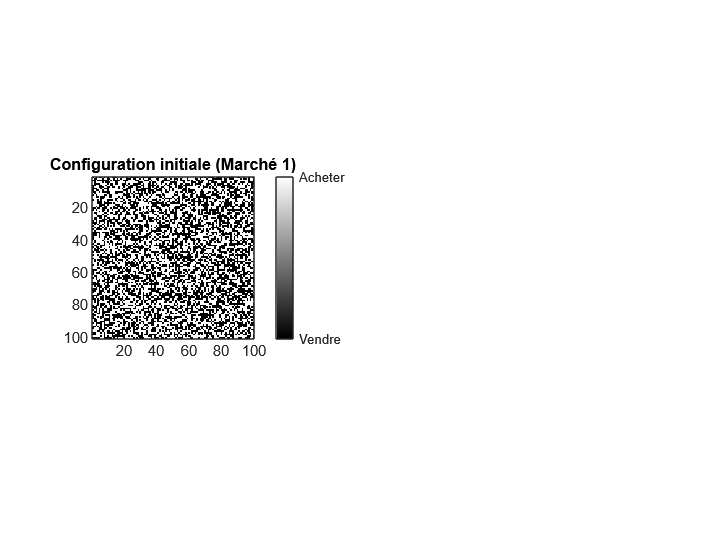

%% Project : Ising model
% Econophysics : Financial modelling with natural Science
% Par Sidney Verré, Adam GUEMOUNE, Bolarinwa SOUHOUIN, Yannick Ivan Hyacime TAPSOBA

clear all;
close all;
clc;

%% Paramètres du système
n = 100;           % Taille de la grille
K_all = 3;         % Nombre de marchés (stocks)
alpha = 20;        % Paramètre d'inertie individuelle
gamma = 0.15;      % Paramètre de contagion entre marchés
beta = 2;          % Paramètre de température (1/T)
n_iter = 10000;    % Nombre d'itérations (augmenté à 10000 selon le projet)
nD = 1000;         % Fenêtre temporelle pour le calcul de volatilité

rng(123456);       % Seed pour la reproductibilité

%% Initialisation du système
% Création d'une matrice 3D pour représenter les K_all marchés
S = zeros(n, n, K_all);
for i = 1:n
    for j = 1:n
        for k = 1:K_all
            % Initialisation aléatoire des spins [-1, 1]
            S(i,j,k) = sign(rand - 0.5);
        end
    end
end

%% Fonction de calcul de la magnétisation
function magn = magn_mean(System)
    % Calcule la magnétisation moyenne pour chaque marché
    if ndims(System) == 3
        % Pour un système 3D (multi-marchés)
        magn = squeeze(mean(mean(System, 1), 2));
    else
        % Pour un système 2D (mono-marché)
        magn = mean(System(:));
    end
end

%% Fonction de calcul de l'hamiltonien local
function H = H_loc(i, j, k, S, M, alpha, gamma, K_all)
    % Dimensions du système
    n = size(S, 1);
    
    % 1. Terme d'interaction avec les voisins (8-connexité)
    voisins = 0;
    di = [-1, -1, -1, 0, 0, 1, 1, 1];
    dj = [-1, 0, 1, -1, 1, -1, 0, 1];
    
    for d = 1:8
        % Gestion des conditions périodiques
        i_voisin = mod(i + di(d) - 1, n) + 1;
        j_voisin = mod(j + dj(d) - 1, n) + 1;
        voisins = voisins + S(i_voisin, j_voisin, k);
    end
    
    % 2. Terme de champ moyen local
    champ_moyen = alpha * S(i, j, k) * abs(M(k));
    
    % 3. Terme de couplage inter-marchés
    couplage = 0;
    for k1 = 1:K_all
        if k1 ~= k
            couplage = couplage + M(k1);
        end
    end
    
    % Hamiltonien local complet
    H = -voisins + champ_moyen - gamma * couplage;
end

%% Fonction de mise à jour des spins
function S_new = update_spin(S, M, alpha, gamma, beta, K_all)
    n = size(S, 1);
    S_new = S;  % On part de la configuration actuelle
    
    for i = 1:n
        for j = 1:n
            for k = 1:K_all
                % Calcul de l'hamiltonien local
                h_val = H_loc(i, j, k, S, M, alpha, gamma, K_all);
                
                % Calcul de la probabilité de flip
                % Formule de Glauber: P(flip) = 1/(1+exp(2βh))
                P_flip = 1 / (1 + exp(2 * beta * h_val * S(i, j, k)));
                
                % Décision de changer d'état
                if rand < P_flip
                    S_new(i, j, k) = -S(i, j, k);
                end
            end
        end
    end
end

%% Affichage initial
figure;
subplot(1,2,1);
imagesc(S(:,:,1));
colormap(gray);
colorbar('Ticks', [-1, 1], 'TickLabels', {'Vendre', 'Acheter'});
title('Configuration initiale (Marché 1)');
axis square;


% Calcul de la magnétisation initiale
M_initial = magn_mean(S);
fprintf('Magnétisation initiale: %s\n', mat2str(M_initial, 3));

Magnétisation initiale: [0.0058;-0.0014;0.007]



%% Simulation principale
M_history = zeros(n_iter, K_all);
ret_history = zeros(n_iter, K_all);

for t = 1:n_iter
    % Calcul des magnétisations courantes
    M_current = magn_mean(S);
    
    % Mise à jour des spins
    S = update_spin(S, M_current, alpha, gamma, beta, K_all);
    
    % Stockage des résultats
    M_history(t, :) = M_current;
    
    % Calcul des rendements (log-returns)
    if t > 1
        for k = 1:K_all
            if M_history(t-1, k) ~= 0
                ret_history(t, k) = log(M_current(k) / M_history(t-1, k));
            else
                ret_history(t, k) = 0;
            end
        end
    end
    
    % Affichage de progression
    if mod(t, 1000) == 0
        fprintf('Itération %d/%d terminée\n', t, n_iter);
    end
end

Itération 1000/10000 terminée
Itération 2000/10000 terminée
Itération 3000/10000 terminée
Itération 4000/10000 terminée
Itération 5000/10000 terminée
Itération 6000/10000 terminée
Itération 7000/10000 terminée
Itération 8000/10000 terminée
Itération 9000/10000 terminée
Itération 10000/10000 terminée


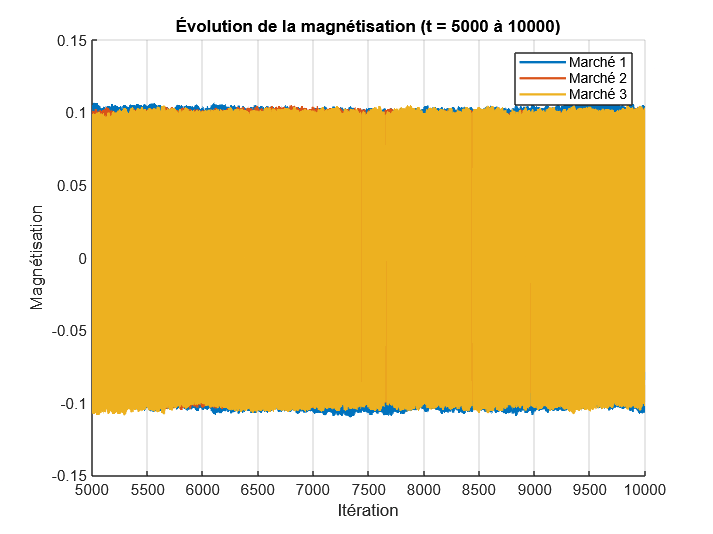


%% Calcul de la volatilité
% σ^{(k)}(t) = (1/nD) * sum_{t'=t}^{t+nD-1} |ret^{(k)}(t')|
volatility = zeros(n_iter, K_all);

for k = 1:K_all
    for t = 1:(n_iter - nD + 1)
        window_returns = abs(ret_history(t:min(t+nD-1, n_iter), k));
        volatility(t, k) = mean(window_returns);
    end
end

%% Visualisation des résultats
% ====================
% Magnétisation et rendements (t ∈ [5000, 10000])
% ====================
start_idx = 5000;
end_idx = 10000;

% Évolution de la magnétisation
figure;
hold on;
colors = lines(K_all);
for k = 1:K_all
    plot(start_idx:end_idx, M_history(start_idx:end_idx, k), 'LineWidth', 1.5, 'Color', colors(k,:));
end
hold off;
title('Évolution de la magnétisation (t = 5000 à 10000)');
xlabel('Itération');
ylabel('Magnétisation');
legend(arrayfun(@(k) sprintf('Marché %d', k), 1:K_all, 'UniformOutput', false));
grid on;


% Rendements
figure;
hold on;
for k = 1:K_all
    plot(start_idx:end_idx, ret_history(start_idx:end_idx, k), 'LineWidth', 1.5, 'Color', colors(k,:));
end

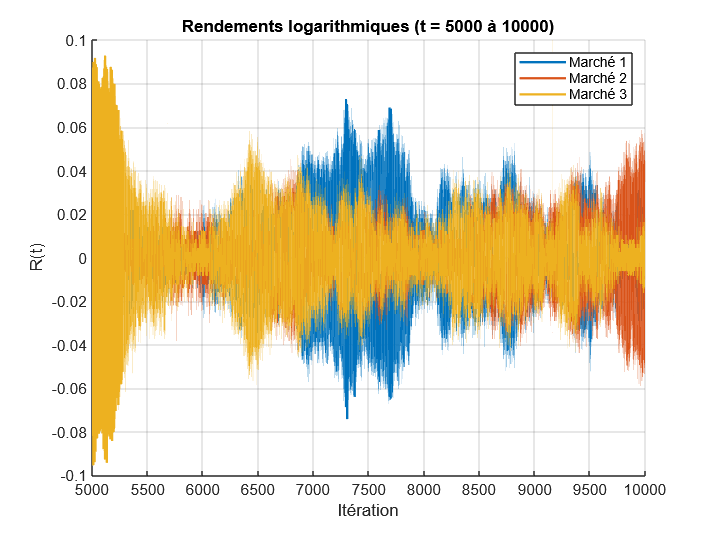

hold off;
title('Rendements logarithmiques (t = 5000 à 10000)');
xlabel('Itération');
ylabel('R(t)');
legend(arrayfun(@(k) sprintf('Marché %d', k), 1:K_all, 'UniformOutput', false));
grid on;

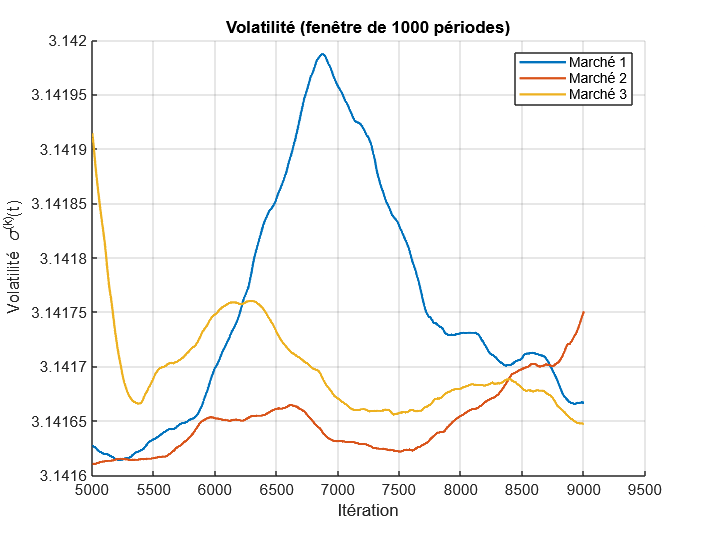


% ====================
% Volatilité (t ∈ [5000, 10000])
% ====================
figure;
hold on;
for k = 1:K_all
    % On ne peut calculer la volatilité que jusqu'à t = n_iter - nD + 1
    vol_end_idx = min(end_idx, n_iter - nD + 1);
    plot(start_idx:vol_end_idx, volatility(start_idx:vol_end_idx, k), 'LineWidth', 1.5, 'Color', colors(k,:));
end
hold off;
title(sprintf('Volatilité (fenêtre de %d périodes)', nD));
xlabel('Itération');
ylabel('Volatilité \sigma^{(k)}(t)');
legend(arrayfun(@(k) sprintf('Marché %d', k), 1:K_all, 'UniformOutput', false));
grid on;


% ====================
% Histogramme des rendements avec ajustement normal
% ====================
for k = 1:K_all
    figure;
    returns = ret_history(start_idx:end_idx, k);
    returns = returns(returns ~= 0);  % Exclure les zéros
    
    % Histogramme
    h = histogram(returns, 50, 'Normalization', 'pdf');
    hold on;
    
    % Ajustement d'une distribution normale
    mu = mean(returns);
    sigma = std(returns);
    x = linspace(min(returns), max(returns), 100);
    y = normpdf(x, mu, sigma);
    plot(x, y, 'r-', 'LineWidth', 2);
    
    title(sprintf('Distribution des rendements - Marché %d (t = 5000 à 10000)', k));
    xlabel('Rendement');
    ylabel('Densité de probabilité');
    legend('Données', sprintf('Normale (\\mu=%.4f, \\sigma=%.4f)', mu, sigma));
    grid on;
    hold off;
end

Error using histogram
Expected input number 1, x, to be real.

Error in histogram>parseinput (line 176)
        validateattributes(x,{'numeric','logical','datetime','duration','categorical'},...

Error in histogram (line 50)
[opts,passthrough,dispatchToCategorical] = parseinput(args,firstaxesinput);


%% Étude de l'influence des paramètres (facultatif)
% Cette section peut être utilisée pour étudier l'effet de alpha ou gamma
% en faisant varier ces paramètres et en réexécutant la simulation

% Exemple pour alpha:
% alphas = [10, 20, 30];
% for a = alphas
%     alpha = a;
%     % Réexécuter la simulation
%     % Calculer et stocker les résultats
% end
% % Comparer les résultats pour différents alpha